# Second Part - 1 dof finger1 & finger2 input

close all; clear all; clc;

## FINGER 1

As first passage we load and extract the necessary data (time and accelerations):

data = load('finger_1.txt');
time = data(:, 1);
acc = data(:, 3);

## 2.1 Sampling Frequency and Meaningful Window

We can immediately compute the sampling frequency of the data:

number_of_samples = size(acc,1);
total_time = max(time);
fs = number_of_samples/total_time;

Let's take a look to the origial acceleration output over the time domain:

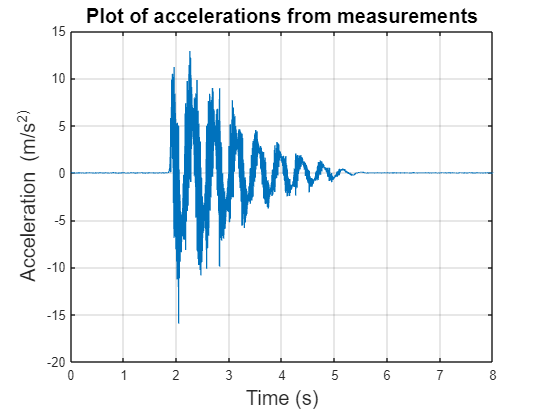

figure(1),
plot(time,acc);
title('Plot of accelerations from measurements','FontSize',15)
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15)
grid on

From the graph we can clearly observe that the acceleration's sensor has started to record the data about 2 seconds before the cart was released, so we focus only on the part on which we are interested:

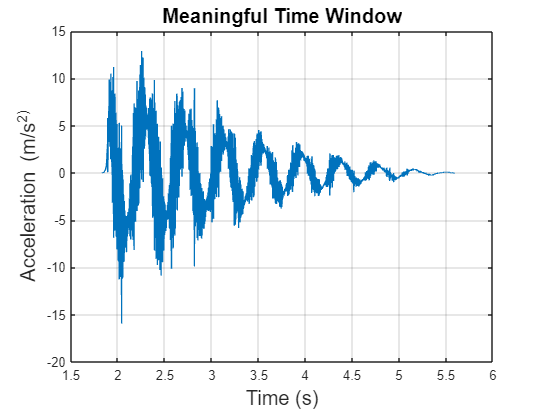

start_time = 1.832734;  % Starting time of the meaningful window in seconds
end_time = 5.590000;    % Ending time of the meaningful window in seconds
start_index = find(time >= start_time, 1);
end_index = find(time >= end_time, 1);

time_window = time(start_index:end_index);
acc_window = acc(start_index:end_index);

figure(2),
plot(time_window, acc_window);
title('Meaningful Time Window','FontSize',15)
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15);
grid on;

From the graph we can clearly see the signal has a non-negligible component of niose

## 2.2 Filtering the noise, find peaks position and the magnitude

In order to have a smooth sinal we can perform a filtering, by computing the moving average on, for example, 1000 samples. We perform the smoothing twice:

n1 = 1000;
s_smooth_cart = smooth(acc_window,n1);
n2 = 1000;
s_smooth2_cart = smooth(s_smooth_cart,n2);

We use the two-time smoothed sigal to find the location (which are the samples number) of the main peaks:

[peak_val, peak_loc] = findpeaks(s_smooth2_cart);

We use the location obtained to evaluate the one-time smoothed signal in those points. Note: we use the one-time smoothed signal beause it is more similar to the real signal with noise.

peaks = s_smooth_cart(peak_loc);        % evaluate at the points of interest
peak_time = time_window(peak_loc);      % find the corresponding time

First we can observe the smoothed signals compared to the original.

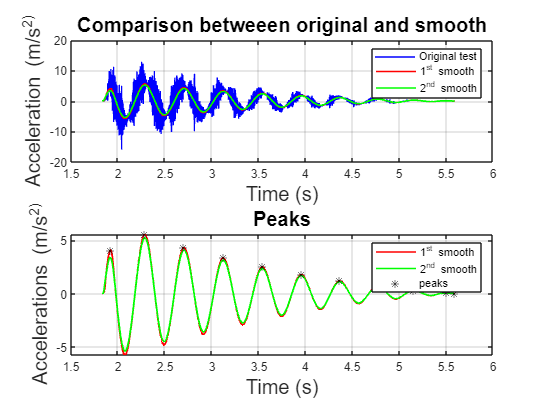

figure(3),
subplot(2,1,1);
plot(time_window, acc_window, 'b');
hold on;
plot(time_window, s_smooth_cart, 'r', 'LineWidth', 1.3);
plot(time_window, s_smooth2_cart, 'g', 'LineWidth', 1.3);
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15);
title('Comparison betweeen original and smooth','FontSize',15);
legend('Original test', '1^{st} smooth', '2^{nd} smooth')
grid on

subplot(2,1,2);
plot(time_window, s_smooth_cart, 'r', 'LineWidth', 1.3);
hold on;
plot(time_window, s_smooth2_cart, 'g', 'LineWidth', 1.3);
plot(peak_time, peaks, 'k*');
xlabel('Time (s)','FontSize',15);
ylabel('Accelerations (m/s^2)','FontSize',15);
title('Peaks','FontSize',15);
legend('1^{st} smooth', '2^{nd} smooth', 'peaks');
grid on;
hold off;

## 2.3 Logarithmic Decrement Technique

We can perform the Logarithmic Decrement Method.

Due to some numerical error in the filtering, we can neglect the first and the last peaks, because since they have small values, they are affected by noise.

delta = log(peaks(2:8)./peaks(3:9));            % logarithmic decrements
mean_delta = mean(delta);                       % average of delta; 6 df
std_delta = std(delta);
T_d = diff(peak_time(2:9));                     % vector of periods of oscillation

Now we can compute the asked quantities with the relative standard deviations:

In some cases we have to use the propagation of error formula:

mean_period = mean(T_d);    % 6 df
std_period = std(T_d);

xi = mean_delta / sqrt(4*pi^2 + mean_delta^2);   % mean damping ratio
std_xi = sqrt(((1/(sqrt(4*pi^2 + mean_delta^2)))-((mean_delta^2/((4*pi^2 + mean_delta^2)^(3/2)))))^2 * std_delta^2);

omega_d = 2*pi / mean_period;                       % natural frequency
std_omega_d = sqrt((-(2*pi)/((mean_period)^2))^2 * std_period^2);

omega_n = omega_d / sqrt(1 - xi^2); % damped natural frequency
std_omega_n = sqrt( ( (1/(sqrt(1-xi^2)))*std_omega_d)^2 + (-(omega_d*xi)/((1-xi^2)^(3/2))*std_xi)^2);

By knowing the mass (m1 = 1.7 kg) We can now estimate also the parameters of the system such as stiffness (k0) and damping (c1) along with their standard deviation:

m1 = 1.7;                   % [kg]

k0 = omega_n^2 * m1;        % [N/m]
std_k0 = sqrt((2*omega_n*m1 * std_omega_n)^2);

c1 = 2 * xi * omega_n * m1; % [N s/m]
std_c1 = sqrt((2*xi*m1 * std_omega_n)^2+(2*omega_n*m1 * std_xi)^2);

To have a better understanding of the results, we have to consider the uncertainty (moe = margin of error) of the computed quantities. Since we are computing the results from a small quantity of data, we are aware that the standard deviation is not a robust estimate of the variability of the data. Therefore I choose express the uncertainty by compute a two-tailed confidence interval of 90% from a t-distribution. Since the number of degree of freedom is 6 (7 - 1 samples) the critical t-value is 2.447.

tv = 2.447;     % critical t-value
sz = size(T_d);
moe_period = tv * (std_period / sqrt(sz(1)));
moe_xi = tv * (std_xi / sqrt(sz(1)));
moe_omega_d = tv * (std_omega_d / sqrt(sz(1)));
moe_omega_n = tv * (std_omega_n / sqrt(sz(1)));
moe_k0 = tv * (std_k0 / sqrt(sz(1)));
moe_c1 = tv * (std_c1 / sqrt(sz(1)));

disp('-----------------------------------------');

-----------------------------------------


disp('----------------Finger 1-----------------');

----------------Finger 1-----------------


disp(['Period of oscillation (T): ' num2str(mean_period) ' s']);

Period of oscillation (T): 0.40974 s


disp(['uncertainty of T: ' num2str(moe_period) ' s']);

uncertainty of T: 0.010405 s


disp(['Damping ratio (xi): ' num2str(xi)]);

Damping ratio (xi): 0.064759


disp(['uncertainty of xi: ' num2str(moe_xi)]);

uncertainty of xi: 0.028189


disp(['Damped natural frequency (ωd): ' num2str(omega_d) ' rad/s']);

Damped natural frequency (ωd): 15.3344 rad/s


disp(['uncertainty of ωd: ' num2str(moe_omega_d) ' rad/s']);

uncertainty of ωd: 0.3894 rad/s


disp(['Natural frequency (ωn): ' num2str(omega_n) ' rad/s']);

Natural frequency (ωn): 15.3667 rad/s


disp(['uncertainty of ωn: ' num2str(moe_omega_n) ' rad/s']);

uncertainty of ωn: 0.39123 rad/s


disp(['Stiffness constant (k0): ' num2str(k0) ' N/m']);

Stiffness constant (k0): 401.4303 N/m


disp(['uncertainty of k0: ' num2str(moe_k0) ' N/m']);

uncertainty of k0: 20.4406 N/m


disp(['Damping constant (c1): ' num2str(c1) ' N s/m']);

Damping constant (c1): 3.3834 N s/m


disp(['uncertainty of c1: ' num2str(moe_c1) ' N s/m']);

uncertainty of c1: 1.4753 N s/m


## FINGER 2

Since the reasoning would be the same, it is possible to perform the same passages for this second dataset:

Load and extract the necessary data (time and accelerations):

data1 = load('finger_2.txt');
time1 = data1(:, 1);
acc1 = data1(:, 3);

## 2.4 Sampling Frequency and Meaningful Window

We can immediately compute the sampling frequency of the data:

number_of_samples1 = size(acc1,1);
total_time1 = max(time1);
fs1 = number_of_samples1/total_time1;

Let's take a look to the origial acceleration output over the time domain:

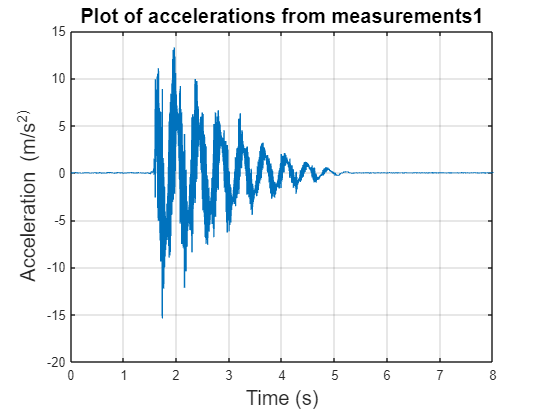

figure(4), clf
plot(time1,acc1);
title('Plot of accelerations from measurements1','FontSize',15)
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15)
grid on

From the graph we can clearly observe that the acceleration's sensor has started to record the data about 2 seconds before the cart was released, so we focus only on the part on which we are interested:

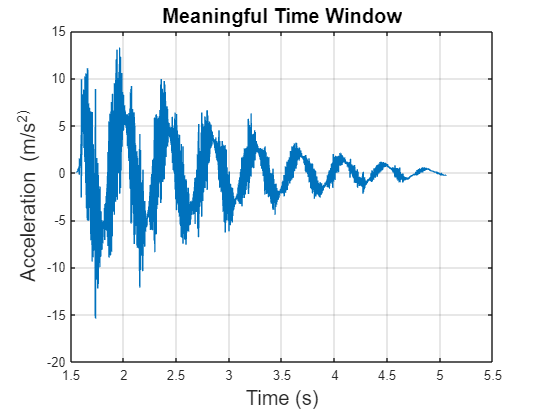

start_time1 = 1.550000;  % Starting time of the meaningful window in seconds
end_time1 = 5.054687;    % Ending time of the meaningful window in seconds
start_index1 = find(time1 >= start_time1, 1);
end_index1 = find(time1 >= end_time1, 1);

time_window1 = time1(start_index1:end_index1);
acc_window1 = acc1(start_index1:end_index1);

figure(5), clf
plot(time_window1, acc_window1);
title('Meaningful Time Window','FontSize',15);
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15);
grid on;

From the graph we can clearly see the signal has a non-negligible component of niose.

## 2.5 Filtering the noise, find peaks position and the magnitude

In order to have a smooth sinal we can perform a filtering, by computing the moving average on, for example, 1000 samples. We perform the smoothing twice:

n11 = 1000;
s_smooth_cart1 = smooth(acc_window1,n1);
n21 = 1000;
s_smooth2_cart1 = smooth(s_smooth_cart1,n2);

We use the two-time smoothed sigal to find the location (which are the samples number) of the main peaks:

[peak_val1, peak_loc1] = findpeaks(s_smooth2_cart1);

We use the location obtained to evaluate the one-time smoothed signal in those points. Note: we use the one-time smoothed signal beause it is more similar to the real signal with noise.

peaks1 = s_smooth_cart1(peak_loc1);    % evaluate at the points of interest
peak_time1 = time_window1(peak_loc1);  % find the corresponding time

First we can observe the smoothed signals compared to the original.

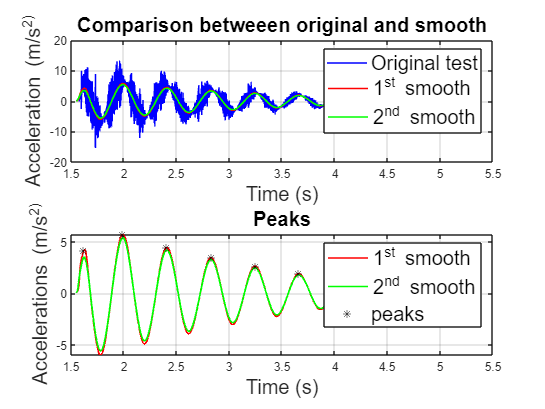

figure(6),
subplot(2,1,1);
plot(time_window1, acc_window1, 'b');
hold on;
plot(time_window1, s_smooth_cart1, 'r', 'LineWidth', 1.3);
plot(time_window1, s_smooth2_cart1, 'g', 'LineWidth', 1.3);
xlabel('Time (s)','FontSize',15);
ylabel('Acceleration (m/s^2)','FontSize',15);
title('Comparison betweeen original and smooth','FontSize',15);
legend('Original test', '1^{st} smooth', '2^{nd} smooth','FontSize',15)
grid on

subplot(2,1,2);
plot(time_window1, s_smooth_cart1, 'r', 'LineWidth', 1.3);
hold on;
plot(time_window1, s_smooth2_cart1, 'g', 'LineWidth', 1.3);
plot(peak_time1, peaks1, 'k*');
xlabel('Time (s)','FontSize',15);
ylabel('Accelerations (m/s^2)','FontSize',15);
title('Peaks','FontSize',15);
legend('1^{st} smooth', '2^{nd} smooth', 'peaks','FontSize',15);
grid on;
hold off;

## 2.3 Logarithmic Decrement Technique

We can perform the Logarithmic Decrement Method.

Due to some numerical error in the filtering, we can neglect the first and the last peaks, because since they have small values, they are affected by noise.

delta1 = log(peaks1(2:8)./peaks1(3:9));            % logarithmic decrements
mean_delta1 = mean(delta1);                       % average of delta; 6 df
std_delta1 = std(delta1);
T_d1 = diff(peak_time1(2:9));                     % vector of periods of oscillation

Now we can compute the asked quantities with the relative standard deviations:

In some cases we have to use the propagation of error formula:

mean_period1 = mean(T_d1);    % 6 df
std_period1 = std(T_d1);

xi1 = mean_delta1 / sqrt(4*pi^2 + mean_delta1^2);   % mean damping ratio
std_xi1 = sqrt(((1/(sqrt(4*pi^2 + mean_delta1^2)))-((mean_delta1^2/((4*pi^2 + mean_delta1^2)^(3/2)))))^2 * std_delta1^2);

omega_d1 = 2*pi / mean_period1;                       % natural frequency
std_omega_d1 = sqrt((-(2*pi)/((mean_period1)^2))^2 * std_period1^2);

omega_n1 = omega_d1 / sqrt(1 - xi1^2); % damped natural frequency
std_omega_n1 = sqrt( ( (1/(sqrt(1-xi1^2)))*std_omega_d1)^2 + (-(omega_d1*xi1)/((1-xi1^2)^(3/2))*std_xi1)^2);

By knowing the mass (m1 = 1.7 kg) We can now estimate also the parameters of the system such as stiffness (k0) and damping (c1):

m11 = 1.7;                      % [kg]

k01 = omega_n1^2 * m11;         % [N/m]
std_k01 = sqrt((2*omega_n1*m11 * std_omega_n1)^2);

c11 = 2 * xi1 * omega_n1 * m11; % [N s/m]
std_c11 = sqrt((2*xi1*m11 * std_omega_n1)^2+(2*omega_n1*m1 * std_xi1)^2);

To have a better understanding of the results, we have to consider the uncertainty (moe = margin of error) of the computed quantities. Since we are computing the results from a small quantity of data, we are aware that the standard deviation is not a robust estimate of the variability of the data. Therefore I choose express the uncertainty by compute a confidence interval of 90% from a t-distribution. Since the number of degree of freedom is 6 (7 - 1 samples) the critical t-value is 2.447.

tv1 = 2.447;     % critical t-value
sz1 = size(T_d1);
moe_period1 = tv1 * (std_period1 / sqrt(sz1(1)));
moe_xi1 = tv1 * (std_xi1 / sqrt(sz1(1)));
moe_omega_d1 = tv1 * (std_omega_d1 / sqrt(sz1(1)));
moe_omega_n1 = tv1 * (std_omega_n1 / sqrt(sz1(1)));
moe_k01 = tv * (std_k01 / sqrt(sz1(1)));
moe_c11 = tv * (std_c11 / sqrt(sz1(1)));

disp('-----------------------------------------');

-----------------------------------------


disp('----------------Finger 2-----------------');

----------------Finger 2-----------------


disp(['Period of oscillation (T): ' num2str(mean_period1) ' s']);

Period of oscillation (T): 0.41079 s


disp(['uncertainty of T: ' num2str(moe_period1) ' s']);

uncertainty of T: 0.0093137 s


disp(['Damping ratio (xi): ' num2str(xi1)]);

Damping ratio (xi): 0.062211


disp(['uncertainty of xi: ' num2str(moe_xi1)]);

uncertainty of xi: 0.025772


disp(['Damped natural frequency (ωd): ' num2str(omega_d1) ' rad/s']);

Damped natural frequency (ωd): 15.2953 rad/s


disp(['uncertainty of ωd: ' num2str(moe_omega_d1) ' rad/s']);

uncertainty of ωd: 0.34678 rad/s


disp(['Natural frequency (ωn): ' num2str(omega_n1) ' rad/s']);

Natural frequency (ωn): 15.325 rad/s


disp(['uncertainty of ωn: ' num2str(moe_omega_n1) ' rad/s']);

uncertainty of ωn: 0.34833 rad/s


disp(['Stiffness constant (k0): ' num2str(k01) ' N/m']);

Stiffness constant (k0): 399.2527 N/m


disp(['uncertainty of k0: ' num2str(moe_k01) ' N/m']);

uncertainty of k0: 18.1497 N/m


disp(['Damping constant (c1): ' num2str(c11) ' N s/m']);

Damping constant (c1): 3.2415 N s/m


disp(['uncertainty of c1: ' num2str(moe_c11) ' N s/m']);

uncertainty of c1: 1.3449 N s/m


Compatib_mean_period = abs(mean_period1 - mean_period) < (moe_period1 + moe_period);
if (Compatib_mean_period == 1)
    disp('Misure compatibili');
end

Misure compatibili


Compatib_xi = abs(xi1 - xi) < (moe_xi1 + moe_xi);
if (Compatib_xi == 1)
    disp('Misure compatibili');
end

Misure compatibili


Compatib_omega_d = abs(omega_d1 - omega_d) < (moe_omega_d1 + moe_omega_d);
if (Compatib_omega_d == 1)
    disp('Misure compatibili');
end

Misure compatibili


Compatib_omega_n = abs(omega_n1 - omega_n) < (moe_omega_n1 + moe_omega_n);
if (Compatib_omega_n == 1)
    disp('Misure compatibili');
end

Misure compatibili


Compatib_k0 = abs(k01 - k0) < (moe_k01 + moe_k0);
if (Compatib_k0 == 1)
    disp('Misure compatibili');
end

Misure compatibili


Compatib_c1 = abs(c11 - c1) < (moe_c11 + moe_c1);
if (Compatib_c1 == 1)
    disp('Misure compatibili');
end

Misure compatibili
